# 四、**单级倒立摆的****LQR****状态调节器设计（选做）**

有一个倒立摆小车系统如图一所示。它由质量为M的小车，长为2L的倒立摆构成，倒立摆的质量为m，铰链在小车上，小车在控制函数u的作用下，沿滑轨在x方向运动，使倒立摆在垂直平面内稳定。

 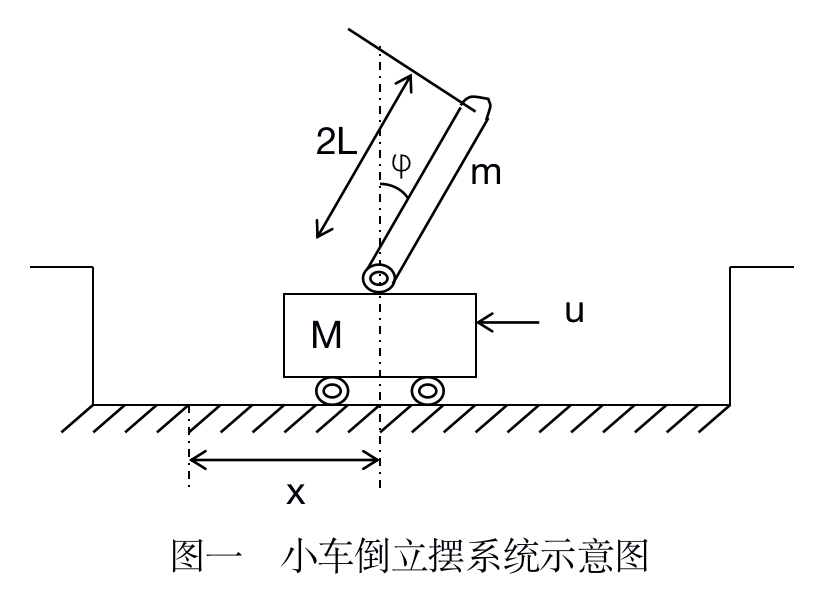

为了简单起见，设倒立摆为均匀细杆，执行机构和轴无摩擦，此时系统的动力学非线性微分方程为：

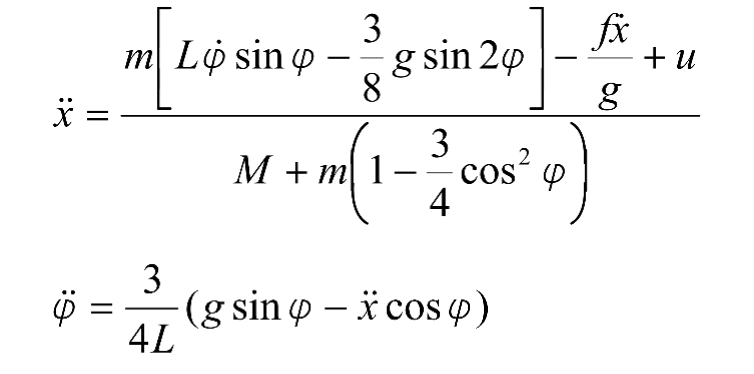

其中，M = 1kg，m = 0.1kg，L = 1m，g = 9.81m/s2，f = 50N/s。

M=1;m=0.1;L=1;g=9.81;f=50;

现设计LQR控制器，使系统倒立摆在如下初始条件下稳定。


$$\pmatrix{
x(0)\cr
\dot{x}(0) \cr
\varphi(0)\cr 
\dot{\varphi}(0)
}

=

\pmatrix{0.05 \cr0\cr0.08\cr0}$$


x0=[0.05 0 0.08 0]';

注：倒立摆偏角j可以通过同轴旋转电位计送出正比j的电信号。

## 4.1 推导状态空间方程

选取状态$x=\pmatrix{x\cr\dot{x}\cr\varphi\cr\dot{\varphi}}$考虑到在平衡位置可以使用近似条件$\sin{x}\sim x,
\cos{x}\sim 1$,并忽略$\varphi\dot{\varphi}$项可得：

%使用Symbolic Math Toolbox计算状态方程系数
syms x phi xdot phidot u;
sinphi=phi;
sin2phi=2*phi;
cosphi=1;
cos2phi=1;
xdotdot=(m*(L*phidot*sinphi-3/8*g*sin2phi)-f*xdot/g+u)/(M+m*(1-3/4*cos2phi))

$$xdotdot = \frac{40\,u}{41}-\frac{2943\,\varphi }{4100}-\frac{200000\,\mathrm{xdot}}{40221}+\frac{4\,\varphi \,\mathrm{phidot}}{41}$$

phidotdot=3/(4*L)*(g*sinphi-xdotdot*cosphi)

$$phidotdot = \frac{32373\,\varphi }{4100}-\frac{30\,u}{41}+\frac{50000\,\mathrm{xdot}}{13407}-\frac{3\,\varphi \,\mathrm{phidot}}{41}$$

ff0=[coeffs(xdotdot);coeffs(phidotdot)];
ff=double(ff0);
A=[0 1 0 0;
    0,ff(1,1),ff(1,3) 0;
    0 0 0 1;
    0 ff(2,1),ff(2,3) 0];
B=[0;ff(1,2);0;ff(1,2)];
C=[1 0 0 0;0 0 1 0];
D=[0;0];
G=ss(A,B,C,D);

## 4.2 **线性系统二次型最优控制律**

使用线性系统二次型最优控制率设计控制律

%使用Control System Toolbox进行线性系统二次型最优控制律
Q=diag([1,1,1,1]);
R=1;
N=zeros(size(Q,1),size(R,2));
K=lqr(A,B,Q,R)%u=-K*x

K =    -1.0000    1.8467   11.6020    4.3004


Ac=A-B*K;
G2=ss(Ac,B,C,D);

## 4.3 性能分析

specs={'r','g','b','y'};
label={'$x$','$\dot{x}$','$\varphi$','$\dot{\varphi}$'};

零输入条件下，初始状态作用的状态和输出响应曲线如下，

从图中可以看出原系统无法达到稳定，而使用线性二次型最优控制后，系统可以迅速达到稳定状态

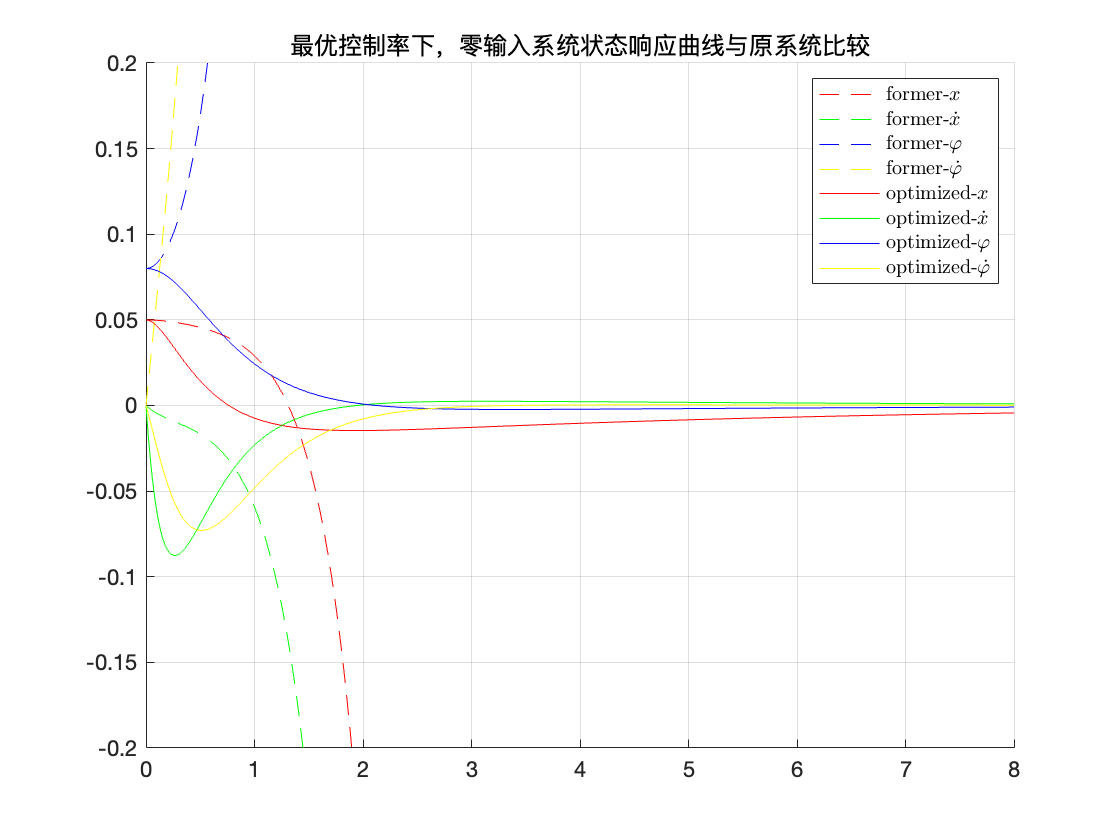

figure()
hold on;
Tfinal=8;
[~,t,x]=initial(G,x0,Tfinal);
[~,t2,x2]=initial(G2,x0,Tfinal);

for i=1:size(x,2)
    plot(t,x(:,i),strcat(specs{i},'--'),'DisplayName',strcat('former-',label{i}))
end
for i=1:size(x,2)
    plot(t2,x2(:,i),specs{i},'DisplayName',strcat('optimized-',label{i}))
end

title('最优控制率下，零输入系统状态响应曲线与原系统比较');
grid;legend('Interpreter',"latex");
ylim([-0.2,0.2]);
hold off

零初始条件下，状态和输出的冲激响应曲线如下，也有和零输入响应类似的结论

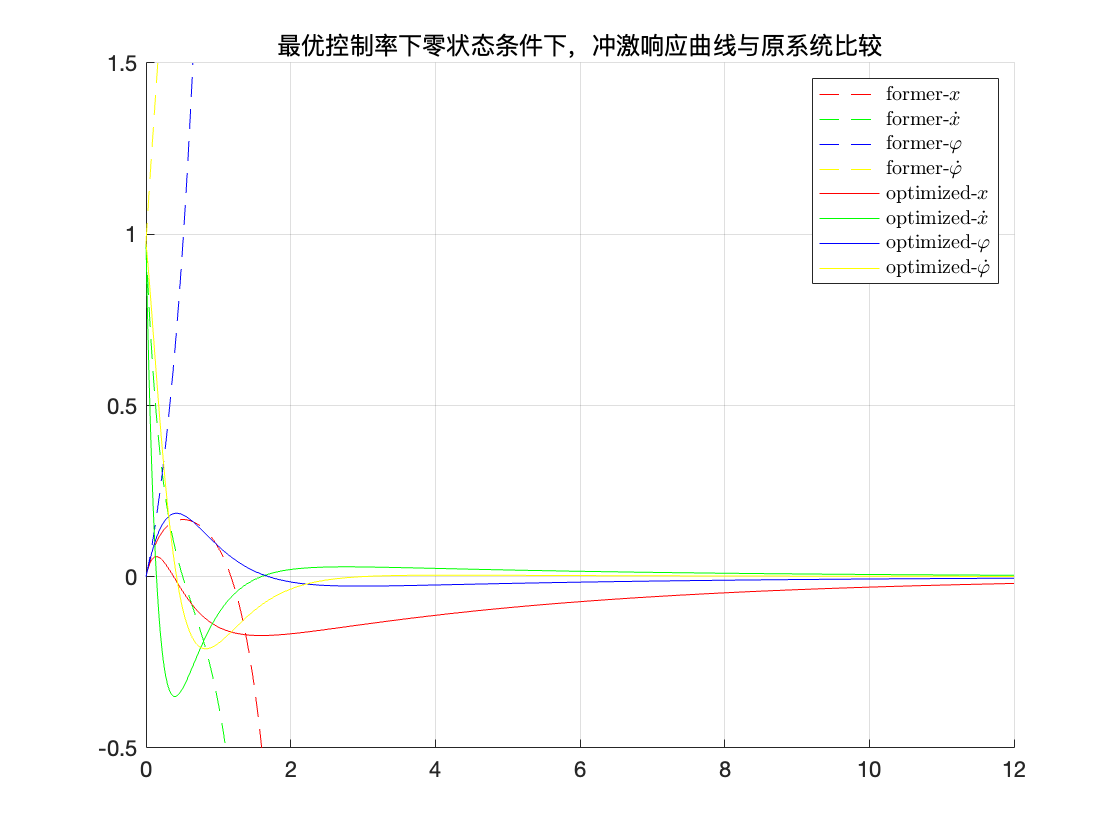

figure()
hold on;
Tfinal=12;
[y,t,x]=impulse(G,Tfinal);
[y2,t2,x2]=impulse(G2,Tfinal);
specs={'r','g','b','y'};

for i=1:size(x,2)
    plot(t,x(:,i),strcat(specs{i},'--'),'DisplayName',strcat('former-',label{i}))
end
for i=1:size(x,2)
    plot(t2,x2(:,i),specs{i},'DisplayName',strcat('optimized-',label{i}))
end

title('最优控制率下零状态条件下，冲激响应曲线与原系统比较');
grid;legend('Interpreter',"latex");
ylim([-0.5,1.5]);
hold off

## 4.4 参考链接

- [https://ww2.mathworks.cn/products/symbolic.html](https://ww2.mathworks.cn/products/symbolic.html)

- https://ww2.mathworks.cn/products/control.html